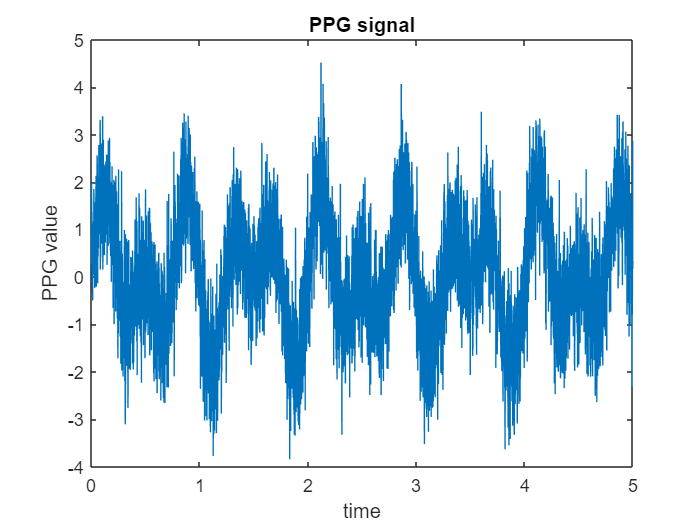

% Sample PPG signal
fs = 1000; % Sampling rate (Hz)
t = 0:1/fs:5; % Time vector (5 seconds)
% Simulated PPG signal with noise
ppg = sin(2*pi*1.5*t) + sin(2*pi*2.5*t) + 0.8*randn(size(t)); 
plot(t,ppg)
xlabel("time")
ylabel("PPG value")
title("PPG signal")

% Apply FFT
fft_ppg = abs(fft(ppg));
fprintf("Amplitude Spectrum ")

Amplitude Spectrum 

fft_ppg

fft_ppg = 	1.0e+03 *

    0.3553    0.3955    0.3875    0.4142    0.4494    0.5123    0.7621    1.7854    1.3261    0.3177    0.0949    0.4413    1.5390    1.6474    0.6050    0.3926    0.2576    0.2187    0.1099    0.1333    0.1725    0.0884    0.0748    0.0826    0.0255    0.0603    0.0251    0.0591    0.0717    0.0724    0.0909    0.0640    0.0171    0.0354    0.0224    0.0478    0.0137    0.0695    0.0682    0.0619    0.0157    0.0404    0.0257    0.0248    0.0358    0.0889    0.0514    0.0377    0.0313    0.0978


freq = (0:length(fft_ppg)-1)*(fs/length(fft_ppg));
fprintf("Frequency Specturm ")

Frequency Specturm 

freq

freq =          0    0.2000    0.3999    0.5999    0.7998    0.9998    1.1998    1.3997    1.5997    1.7996    1.9996    2.1996    2.3995    2.5995    2.7994    2.9994    3.1994    3.3993    3.5993    3.7992    3.9992    4.1992    4.3991    4.5991    4.7990    4.9990    5.1990    5.3989    5.5989    5.7988    5.9988    6.1988    6.3987    6.5987    6.7986    6.9986    7.1986    7.3985    7.5985    7.7984    7.9984    8.1984    8.3983    8.5983    8.7982    8.9982    9.1982    9.3981    9.5981    9.7980


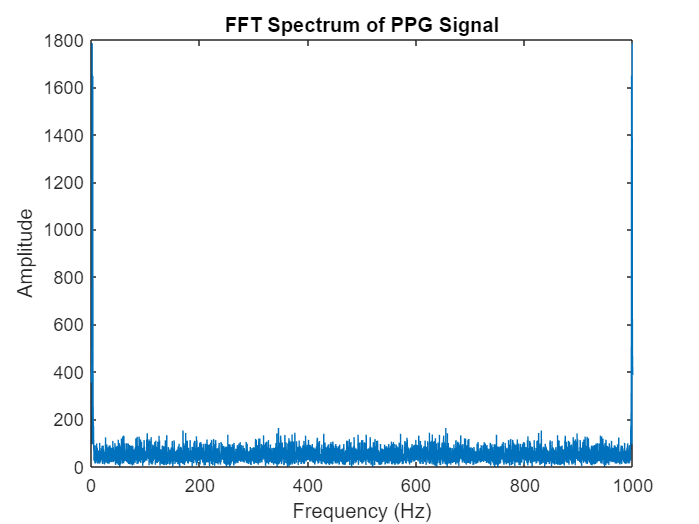


% Plot the frequency spectrum
figure;
plot(freq, fft_ppg);
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('FFT Spectrum of PPG Signal');


% Find the peak frequency
[~, max_idx] = max(fft_ppg);
peak_freq = freq(max_idx);
peak_freq

peak_freq = 1.3997

% Convert peak frequency to heart rate
heart_rate = peak_freq * 60;

% Display heart rate
fprintf('Estimated heart rate: %.2f bpm\n', heart_rate);

Estimated heart rate: 83.98 bpm


clc
clear
clf
image = imread("C:/Users/sharm/OneDrive/Desktop/Maths/ppg.jpg"); 
% Extract the PPG signal
ppg_signal = mean(image, 2);
ppg_signal=reshape(ppg_signal,[],1)

ppg_signal =   255.0000
  255.0000
  255.0000
  255.0000
  255.0000
  255.0000
  255.0000
  255.0000
  254.7889
  244.2596


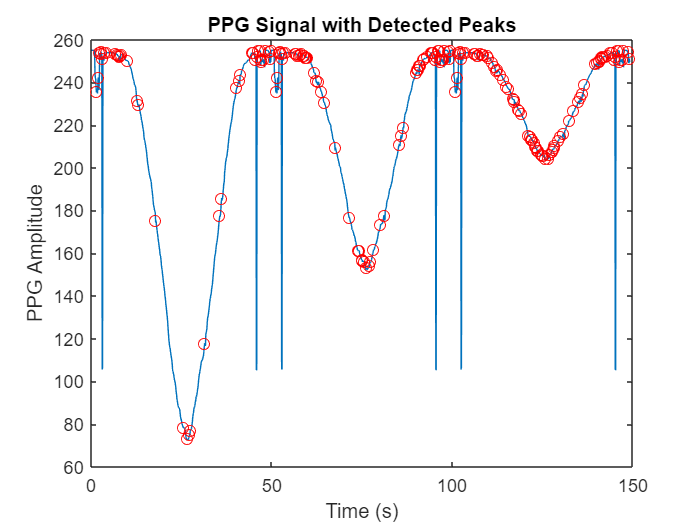

% Detect peaks
[peaks, locations] = findpeaks(ppg_signal); 
sampling_rate=10;
fft_result = fft(ppg_signal);
% Calculate heart rate
time_between_peaks = diff(locations);
heart_rate = 60 / mean(time_between_peaks);
% Plotting the results
t = 1:length(ppg_signal); % Assuming a time-based PPG signal
time_in_seconds = t / sampling_rate; % Convert to time in seconds
plot(time_in_seconds, ppg_signal);
hold on;
plot(locations / sampling_rate, peaks, 'ro');
xlabel('Time (s)');
ylabel('PPG Amplitude');
title('PPG Signal with Detected Peaks');




% Display the heart rate
disp(['Heart Rate: ' num2str(heart_rate*10) ' bpm']);

Heart Rate: 76.4746 bpm


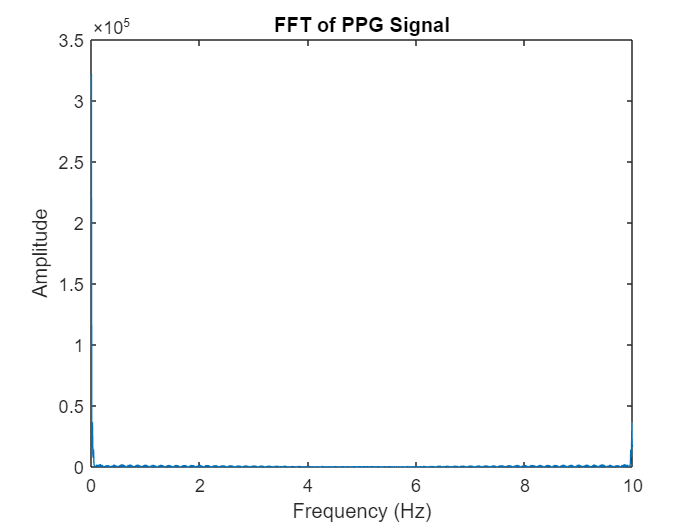

clf

frequencies = (0:length(fft_result)-1) * (sampling_rate / length(fft_result));
plot(frequencies, abs(fft_result));
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('FFT of PPG Signal');

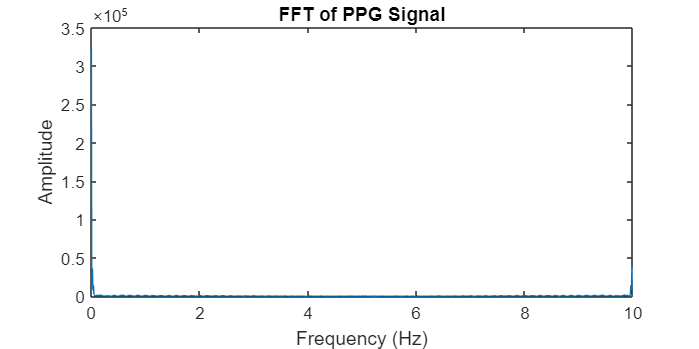

clf
clf
figure('Position', [100, 100, 800, 400]); % Adjust the figure size as needed

frequencies = (0:length(fft_result)-1) * (sampling_rate / length(fft_result));
plot(frequencies, abs(fft_result));
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('FFT of PPG Signal');